clear all; close all;
type = 'real';
pen_list(1,:) = 'P05';
pen_list(2,:) = 'P06';
pen_list(3,:) = 'P08';
pen_list(4,:) = 'P13';
num_pen = size(pen_list,1);
for pen_no = 1:num_pen
    pen = pen_list(pen_no,:);
    %Give the correct directory with Kilosorted files
    data_root = ['//media/alex/4TB SSD/DATA/Ronnie_23_01_2018/bin_files/Preprocessed/CRA_done/',pen,'-reverb_with_noise_same_cra/',pen,'-reverb_with_noise_same_cra_sorted'];
    %Give the correct Benware Grid folder
    grid_root = ['/media/alex/4TB SSD/DATA/Ronnie_23_01_2018/benware_gridinfo/',pen,'-reverb_with_noise_same'];
    sound_files_root = '/media/alex/4TB SSD/DATA/Ronnie_23_01_2018/reverb_with_noise_stimuli/wav_files/reverb_with_noise_same';
    sahani_path = ['/media/alex/4TB SSD/DATA/Ronnie_23_01_2018/metadata/',pen,'-reverb_with_noise_same_psth_sahani'];
    synch_path = ['/media/alex/4TB SSD/DATA/Ronnie_23_01_2018/metadata/synch_ch_reverbwithnoisesame_',pen];
    
    
    NPSP_val = 40; %The NPSP val that is used fir thresholding the 'good clusters'
    time_bin_ms = 10; %The size of the time bin for the cochleagram and psth in ms
    n_h = 30; %The number of history steps for the STRF
    
    min_trig_length_s = 20; %The minmum trigger length in seconds. This will depend on the stimulus. It is best practice to check the synch channel always
    fs = 30000; %Sampling rate in seconds
    qualityOpt = 'nonoise'; %Which untis you want to analyse
    %% Generate the cochleagram
    [coch,t_s] = cochleagram_alex(sound_files_root,time_bin_ms,n_h);
    %% Get the synch channel
    load(synch_path);
    %% Get the triggers
    if strcmp(pen,'P06')
        [start_time_ms] = get_triggers2(synch_ch,min_trig_length_s,fs);
    else
        [start_time_ms] = get_triggers(synch_ch,min_trig_length_s,fs);
    end
    %% Get the spike times
    Y = get_spike_times(data_root,qualityOpt);
    %% Load the psth_sahani and sort clusters
    psth_sahani = 0;
    load(sahani_path);
    count = 0;
    good_clusters = 0;
    for cluster_no = 1:numel(psth_sahani)
        if psth_sahani(cluster_no).NPSP < NPSP_val
            count = count + 1;
            good_clusters(count,1) = psth_sahani(cluster_no).cluster_id;
            good_clusters(count,2) = psth_sahani(cluster_no).NPSP;
        end
    end
    good_clusters = sortrows(good_clusters,2);
    good_cluster_id = good_clusters(:,1);
    no_good_clusters = numel(good_cluster_id);
    %% Generate the PSTHs
    n_h = coch(1).params.n_h;
    psth_all = get_psth_strf(Y,start_time_ms,t_s,grid_root,good_cluster_id,n_h);
    
    for clust = 1:length(psth_all)
        psth_all(clust).NPSP = good_clusters(clust,2);
    end
    
    NPSP{pen_no} = reach(psth_all,'NPSP');

    
    anech_psth = reach(psth_all,'anech').*(1000/time_bin_ms);
    anech_psth = reshape(anech_psth,numel(psth_all(1).anech),no_good_clusters);
    meanfire_anech_t{pen_no} = mean(anech_psth);
    var_anech_t{pen_no} = var(anech_psth);
    reverb1_psth = reach(psth_all,'reverb1').*(1000/time_bin_ms);
    reverb1_psth = reshape(reverb1_psth,numel(psth_all(1).reverb1),no_good_clusters);
    var_reverb1_t{pen_no} = var(reverb1_psth);
    meanfire_reverb1_t{pen_no} = mean(reverb1_psth);
    reverb2_psth = reach(psth_all,'reverb2').*(1000/time_bin_ms);
    reverb2_psth = reshape(reverb2_psth,numel(psth_all(1).reverb2),no_good_clusters);
    meanfire_reverb2_t{pen_no} = mean(reverb2_psth);
    var_reverb2_t{pen_no} = var(reverb2_psth);
    
    total_var{pen_no} = var([anech_psth;reverb1_psth;reverb2_psth]);
    
    
    var_cond{pen_no} = var([meanfire_anech_t{pen_no};meanfire_reverb1_t{pen_no};meanfire_reverb2_t{pen_no}]);
    mean_cond{pen_no} = mean([var_anech_t{pen_no};var_reverb1_t{pen_no};var_reverb2_t{pen_no}]);
end

Check out presentation number 40


== Generating PSTHs ==
Starting parallel pool (parpool) using the 'local' profile ...
connected to 20 workers.
== Processing cluster 1/112 ==
== Processing cluster 2/112 ==
== Processing cluster 3/112 ==
== Processing cluster 4/112 ==
== Processing cluster 5/112 ==
== Processing cluster 6/112 ==
== Processing cluster 8/112 ==
== Processing cluster 10/112 ==
== Processing cluster 12/112 ==
== Processing cluster 15/112 ==
== Processing cluster 18/112 ==
== Processing cluster 21/112 ==
== Processing cluster 24/112 ==
== Processing cluster 27/112 ==
== Processing cluster 30/112 ==
== Processing cluster 33/112 ==
== Processing cluster 36/112 ==
== Processing cluster 39/112 ==
== Processing cluster 42/112 ==
== Processing cluster 45/112 ==
== Processing cluster 60/112 ==
== Processing cluster 51/112 ==
== Processing cluster 54/112 ==
== Processing cluster 63/112 ==
== Processing cluster 57/112 ==
== Processing cluster 7/112 ==
== Processing cluster 9/112 ==
== Processing cluster 11/112 ==
==

== Generating PSTHs ==
== Processing cluster 1/49 ==
== Processing cluster 2/49 ==
== Processing cluster 3/49 ==
== Processing cluster 4/49 ==
== Processing cluster 5/49 ==
== Processing cluster 6/49 ==
== Processing cluster 8/49 ==
== Processing cluster 10/49 ==
== Processing cluster 12/49 ==
== Processing cluster 14/49 ==
== Processing cluster 16/49 ==
== Processing cluster 18/49 ==
== Processing cluster 20/49 ==
== Processing cluster 22/49 ==
== Processing cluster 24/49 ==
== Processing cluster 26/49 ==
== Processing cluster 28/49 ==
== Processing cluster 30/49 ==
== Processing cluster 31/49 ==
== Processing cluster 32/49 ==
== Processing cluster 34/49 ==
== Processing cluster 11/49 ==
== Processing cluster 13/49 ==
== Processing cluster 19/49 ==
== Processing cluster 23/49 ==
== Processing cluster 37/49 ==
== Processing cluster 21/49 ==
== Processing cluster 25/49 ==
== Processing cluster 36/49 ==
== Processing cluster 38/49 ==
== Processing cluster 27/49 ==
== Processing cluster 2

Check out presentation number 25


Check out presentation number 26


Check out presentation number 27


Check out presentation number 28


Check out presentation number 29


Check out presentation number 30


Check out presentation number 31


Check out presentation number 32


Check out presentation number 33


Check out presentation number 34


Check out presentation number 35


Check out presentation number 36


Check out presentation number 37


Check out presentation number 38


== Generating PSTHs ==
== Processing cluster 1/46 ==
== Processing cluster 2/46 ==
== Processing cluster 3/46 ==
== Processing cluster 4/46 ==
== Processing cluster 5/46 ==
== Processing cluster 6/46 ==
== Processing cluster 8/46 ==
== Processing cluster 10/46 ==
== Processing cluster 12/46 ==
== Processing cluster 14/46 ==
== Processing cluster 16/46 ==
== Processing cluster 18/46 ==
== Processing cluster 20/46 ==
== Processing cluster 22/46 ==
== Processing cluster 24/46 ==
== Processing cluster 26/46 ==
== Processing cluster 27/46 ==
== Processing cluster 28/46 ==
== Processing cluster 29/46 ==
== Processing cluster 30/46 ==
== Processing cluster 35/46 ==
== Processing cluster 32/46 ==
== Processing cluster 15/46 ==
== Processing cluster 11/46 ==
== Processing cluster 33/46 ==
== Processing cluster 34/46 ==
== Processing cluster 31/46 ==
== Processing cluster 36/46 ==
== Processing cluster 19/46 ==
== Processing cluster 21/46 ==
== Processing cluster 7/46 ==
== Processing cluster 23

== Generating PSTHs ==
== Processing cluster 1/45 ==
== Processing cluster 2/45 ==
== Processing cluster 3/45 ==
== Processing cluster 4/45 ==
== Processing cluster 5/45 ==
== Processing cluster 6/45 ==
== Processing cluster 8/45 ==
== Processing cluster 10/45 ==
== Processing cluster 12/45 ==
== Processing cluster 14/45 ==
== Processing cluster 16/45 ==
== Processing cluster 18/45 ==
== Processing cluster 20/45 ==
== Processing cluster 22/45 ==
== Processing cluster 24/45 ==
== Processing cluster 26/45 ==
== Processing cluster 27/45 ==
== Processing cluster 28/45 ==
== Processing cluster 29/45 ==
== Processing cluster 30/45 ==
== Processing cluster 34/45 ==
== Processing cluster 35/45 ==
== Processing cluster 36/45 ==
== Processing cluster 19/45 ==
== Processing cluster 33/45 ==
== Processing cluster 25/45 ==
== Processing cluster 31/45 ==
== Processing cluster 11/45 ==
== Processing cluster 7/45 ==
== Processing cluster 21/45 ==
== Processing cluster 13/45 ==
== Processing cluster 32

Plot the results

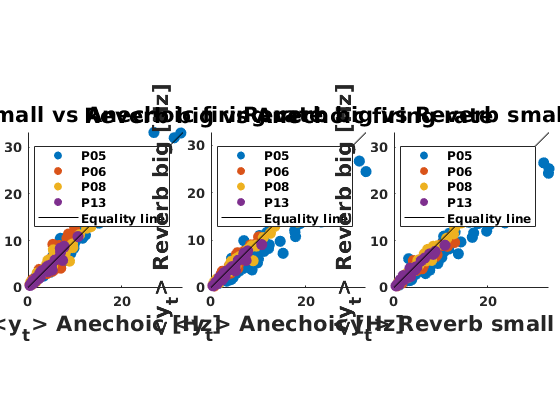

sz = 70;
num_columns = 3;
num_rows = 1;
per = 0.005;
edgel = 0.05; edger = 0.02; edgeh = per; edgeb = per; space_h = 0.05; space_v = per;
[pos]=subplot_pos(num_rows,num_columns,edgel,edger,edgeh,edgeb,space_h,space_v);

figure;
subplot('position',pos{1});
hold on;
for pen_no = 1:num_pen
    scatter(meanfire_anech_t{pen_no},meanfire_reverb1_t{pen_no},sz,'filled');
    max_val(pen_no) = max([meanfire_anech_t{pen_no},meanfire_reverb1_t{pen_no}]);
end
lim_max = max(max_val);
set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('<y_t> Anechoic [Hz]','FontSize',16,'FontWeight','bold');
ylabel('<y_t> Reverb small [Hz]','FontSize',16,'FontWeight','bold');
title(['Reverb small vs Anechoic firing rate'],'FontSize',16,'FontWeight','bold');
colormap('jet');
axis equal;
l = [0 lim_max];
xlim(l);
ylim(l);
hline = refline(1,0);
hline.Color = 'k';
legend('P05','P06','P08','P13','Equality line');
hold off;

subplot('position',pos{2});
hold on;

for pen_no = 1:num_pen
    scatter(meanfire_anech_t{pen_no},meanfire_reverb2_t{pen_no},sz,'filled');
    max_val(pen_no) = max([meanfire_anech_t{pen_no},meanfire_reverb2_t{pen_no}]);
end
lim_max = max(max_val);
set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('<y_t> Anechoic [Hz]','FontSize',16,'FontWeight','bold');
ylabel('<y_t> Reverb big [Hz]','FontSize',16,'FontWeight','bold');
title(['Reverb big vs Anechoic firing rate'],'FontSize',16,'FontWeight','bold');
colormap('jet');
axis equal;

l = [0 lim_max];
xlim(l);
ylim(l);
hline = refline(1,0);
hline.Color = 'k';
legend('P05','P06','P08','P13','Equality line');
hold off;

subplot('position',pos{3});
hold on;

for pen_no = 1:num_pen
    scatter(meanfire_reverb1_t{pen_no},meanfire_reverb2_t{pen_no},sz,'filled');
    max_val(pen_no) = max([meanfire_reverb1_t{pen_no},meanfire_reverb2_t{pen_no}]);
end
lim_max = max(max_val);
set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('<y_t> Reverb small [Hz]','FontSize',16,'FontWeight','bold');
ylabel('<y_t> Reverb big [Hz]','FontSize',16,'FontWeight','bold');
title(['Reverb big vs Reverb small firing rate'],'FontSize',16,'FontWeight','bold');
colormap('jet');
axis equal;
l = [0 lim_max];
xlim(l);
ylim(l);
hline = refline(1,0);
hline.Color = 'k';
legend('P05','P06','P08','P13','Equality line');
hold off;

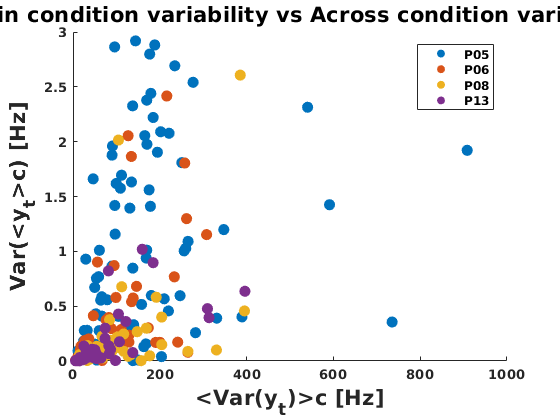


figure;
hold on;

for pen_no = 1:num_pen
    scatter(mean_cond{pen_no},var_cond{pen_no},sz,'filled');
end

set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('<Var(y_t)>c [Hz]','FontSize',16,'FontWeight','bold');
ylabel('Var(<y_t>c) [Hz]','FontSize',16,'FontWeight','bold');
title(['Within condition variability vs Across condition variability'],'FontSize',16,'FontWeight','bold');

ylim([0 3]);
legend('P05','P06','P08','P13' );
hold off;

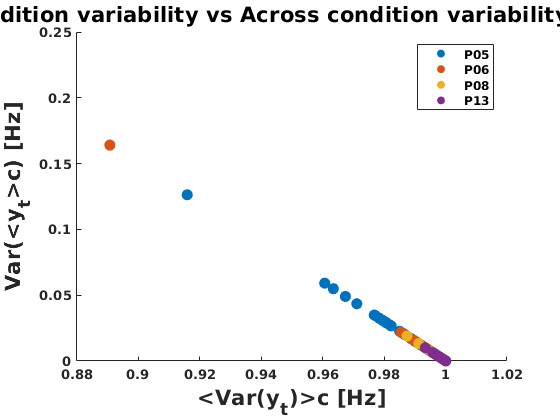


figure;
hold on;

for pen_no = 1:num_pen
    norm_mean_cond{pen_no} = mean_cond{pen_no}./total_var{pen_no};
    norm_var_cond{pen_no} = var_cond{pen_no}./total_var{pen_no};
    scatter(norm_mean_cond{pen_no},norm_var_cond{pen_no},sz,'filled');
end

set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('<Var(y_t)>c [Hz]','FontSize',16,'FontWeight','bold');
ylabel('Var(<y_t>c) [Hz]','FontSize',16,'FontWeight','bold');
title(['Within condition variability vs Across condition variability Normalized'],'FontSize',16,'FontWeight','bold');

ylim([0 0.25]);
legend('P05','P06','P08','P13' );
hold off;